# **demo03 of Im2mesh package**

demo03 - Export: save mesh as inp, bdf, and msh file; save geometry as geo file or PSLG data.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Overview

This demo has 2 parts. 

- Part 1. Export mesh

- Part 2. Export geometry

We'll use function printInp2d, printBdf2d, and printMsh to export mesh. Check the link below to learn about the input arguments for these functions.

[https://github.com/mjx888/writeMesh/blob/main/README.md](https://github.com/mjx888/writeMesh/blob/main/README.md)

## Part 1. Export mesh

### Generate mesh 

First, we'll use function im2mesh to generate mesh. In the next step, we'll export the mesh.

Import image Circle.tif.

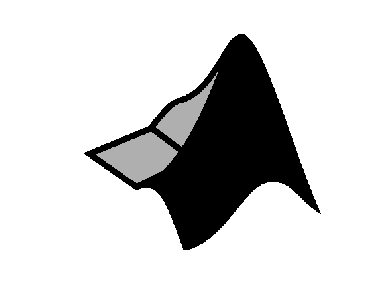

im = imread('logo.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.tolerance = 1;

[ vert, tria, tnum, vert2, tria2 ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          9                125                108
         10                125                218
         17                158                433


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                255                108
         15                272                108
         20                284               1509
         29                299               1821


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                 39               1809



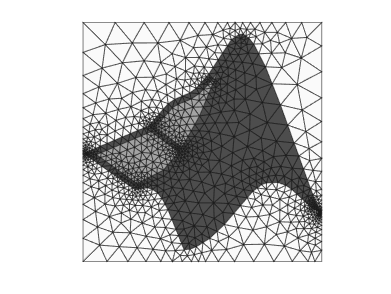

plotMeshes( vert, tria, tnum )

### Prepare for mesh export

Setup scale.

% physical dimensions of a pixel in the image
dx = 0.2;

Scale node coordinates according to dx.

% scale node coordinates of linear elements
vert = vert * dx;

% scale node coordinates of quadratic elements
vert2 = vert2 * dx;

### Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

The exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in the mesh.

#### Linear element

Before exporting, we specify element type and precision.

precision is the number of digits to the right of the decimal point.

ele_type = 'CPS3';
precision = 8;

Write mesh to inp file.

file_name = 'test_linear.inp';
printInp2d( vert, tria, tnum, ele_type, precision, file_name );

printInp2d Done! Check the inp file!


#### Quadratic element

We can do the same operation to quadratic elements. 

ele_type = 'CPS6';
precision = 8;
file_name = 'test_quadratic.inp';

printInp2d( vert2, tria2, tnum, ele_type, precision, file_name );

printInp2d Done! Check the inp file!


### Export as bdf file (Nastran bulk data)

We use function printBdf2d to write 2d mesh to bdf file.

precision = 8;
file_name = 'test_2d.bdf';

printBdf2d( vert, tria, tnum, [], precision, file_name );

printBdf2d Done! Check the bdf file!


### Export as msh file (Gmsh mesh file)

We use function printMsh to write 2d mesh to msh file.

precision = 8;
file_name = 'test_2d.msh';

printMsh( vert, tria, tnum, [], precision, file_name );

printMsh Done! Check the msh file!


### Other file formats

For other formats, we can open the msh file in Gmsh and then export as other file formats.

Gmsh supports a lot of mesh file formats, such as STL, KEY, and VTK.

### Comments

Im2mesh can also export mesh as .node/.ele file using function printTria.

Function printTria was written by me many years ago but I didn't test it.

clearvars

## Part 2. Export geometry

We can save polygonal boundaries (obtained from an image) as geo file or PSLG data.

### Obtain polygonal boundary

Import image Circle.tif.

im = imread('logo.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

We can get boundries from image. We have demostrate how to do this in example3 of demo01.mlx

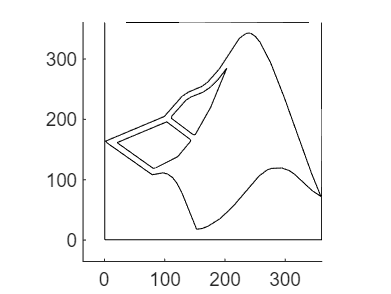

opt = [];       % reset opt
opt.tolerance = 1;
opt.tf_mesh = false;

bounds = im2mesh( im, opt );
plotBounds( bounds )

### Export as geo file (for Gmsh)

geo file is a text file that contains Gmsh’s own scripting language. It’s used to define geometry and mesh generation instructions for Gmsh.

% setup parameters
opt = [];   % reset
opt.tf_includeMesh = false;

path_to_geo = 'test.geo';

bounds2geo( bounds, path_to_geo, opt );

bounds2geo Done! Check the geo file!


### Export as dxf file (CAD)

path_to_geo = 'test.dxf';

printDxf( bounds, path_to_geo );

printDxf Done! Check the dxf file!


### Export as PSLG

We can save polygonal boundaries as PSLG data.

PSLG is planar straight-line graphs. It's the input for mesh generators.

PSLG is represent by these 3 variables: node, edge, part

- node - V-by-2 array. x,y coordinates of vertices. Each row is one vertex.

- edge - E-by-2 array. Node numbering of two connecting vertices of edges. Each row is one edge.

- part - cell array. Used to record phase info. part{i} is edge indexes of the i-th phase, indicating which edges make up the boundary of the i-th phase.

We can use function getPolyNodeEdge and regroup to obtain these 3 variables (node, edge, part).

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );
[ node, edge, part ] = regroup( poly_node, poly_edge );

We may save them them for future usage.

path_file_name = 'PSLG.mat';
save( path_file_name, 'node', 'edge', 'part' );

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo